# Pizza3 - WORKSHOP - PostTreamement - Part 2bis

INRAE\Han Chen, Olivier Vitrac - rev. 2023-09-10

## 1. Synopsis

This extension of the Part2 discusses advanced shear-stress details beyond those presented in Part2. It uses in particular the last features introduced recently: local vrial stress tensor calculated along with Landshoff and Hertz forces and Cauchy stresses reconstructed from projected forces on a Cartesian grid.

The main purpose of this document is to encourage a common understanding how the Landshoff forces can be equilibrated with Hertz contact forces and lead to a steady state. The physical origin and the mathematical formalism of theses forces are very different in nature and emerge from large simulations due to the transfer of momentum mediated between all these forces.

*The main important equation: how Hertz contacts can develop a force which give sense of friction at wall and equates the shear stress in the flow regardless of the rigidity of Hertz contacts? There is a possible direct validation by noting that the The viscous tensor component is associated to the flow (x) can be defined independently from forces:*

                                      
$$\tau_{xy} = \mu \left( \frac{\partial u}{\partial y} \right)$$


In MD-like simulations, a similar stress can be derived from the virial stress tensor as:

                                      
$$\sigma_{\alpha\beta} = \frac{1}{2V} \sum_{i<j} r_{ij,\alpha} f_{ij,\beta}$$


where $V$ is the volume, $r_{ij,\alpha}$ is the $\alpha$-component of the distance vector between particles $i$, $j$ , and $f_{ij,\beta}$ is the $\beta$-component of the force between particles $i$ and $j$.

For a validation based on `example2` results, the most relevant components are those relating to shear and normal forces, specifically  $\sigma_{xy}$ and $\sigma_{yy}$. 

- $\sigma_{xy}$ corresponds to the shear effects and should be closely related to the SPH-based shear stress $\tau_{xy}$  in the fluid. This component would be a primary point of comparison.

- $\sigma_{yy}$ captures the effects of the Hertzian contacts along the $y$-direction (i.e., the direction opposite to which the wall is moving). In the Hertz contact model, the "macroscopic" normal force is acting along the $y$-direction, which contributes to this component.

Therefore, based on the equality of mechanical states between the fluid and the wall, we should expect:

                                
$$\sigma_{xy}^{\text{SPH}} = \sigma_{xy}^{\text{Hertz}}  \textrm{(shear)} \\
\sigma_{yy}^{\text{SPH}} = \sigma_{yy}^{\text{Hertz}} \textrm{(normal)} \\
\textrm{which reads (first index: direction, second index: vcomponent)} \\
\sigma_{21}^{\text{SPH}} = \sigma_{21}^{\text{Hertz}} \\
\sigma_{22}^{\text{SPH}} = \sigma_{22}^{\text{Hertz}} $$


## 2. Theory and numerical implementation

### 2.1 Landshoff forces and their virial approximation: `forceLandshoff` 

#### 2.1.1. Function Description

The function `forceLandshoff` computes Landshoff forces, also known as viscous pressures, between fluid atoms in Smoothed-Particle Hydrodynamics (SPH) simulations. The function can also calculate the virial stress tensor and associated normal vectors. It is designed to be computationally efficient by leveraging vectorization.

#### 2.1.2. Inputs

-  `X`: $n_X \times 3$ matrix containing the coordinates of the atoms.

- `vX`:  $n_X \times 3$ matrix containing the velocity components of the atoms.

- `V`:  $n_X \times 1$ cell array representing the Verlet list for each atom, detailing its neighboring atoms.

- `config`: A structure containing various parameters like the gradient kernel function, smoothing length $h$, speed of sound $c_0$, coefficient $q_1$, density $\rho$, and mass of the bead $m$.

#### 2.1.3. Outputs

Depending on the number of requested outputs, the function can return:

- `F`: $n_X \times 3$ vector of Landshoff forces for each atom.

-  `W`: $n_X \times 9$ matrix of virial stress tensors.

-  `n`: $n_X \times 3$ matrix of normal vectors.

#### 2.1.4. Equation

The Landshoff force $F_{ij}$  between two fluid particles $i$ and $j$ is calculated as follows:

                        
$$\[
F_{ij} = \alpha \frac{m_im_j}{\langle\rho\rangle} \left( \frac{v_{ij} \cdot r_{ij}}{r_{ij}^2 + \epsilon h^2} \right) \nabla_{ij} W(r_{ij})
\]$$


        where

        - $\alpha = q_1 \times c_0 \times h$ 

        - $m_i,m_j$  are the masses of the bead $i$ and $j$

        - $\rho$  is the fluid density

        - $v_{ij}$  is the relative velocity between particles $i$  and $j$ 

        - $r_{ij}$  is the position vector between particles $i$  and $j$ 

        - $\nabla W(r_{ij})$  is the gradient of the smoothing kernel (1D gradient)

        - $\epsilon h^2$  is a small number to prevent division by zero

        - $h$  is the smoothing length

#### 2.1.5. Numerical Implementation

The primary loop in the function iterates over each atom (primary atom) and uses its corresponding Verlet list to identify the neighbors. The core of the algorithm uses this list to calculate the **Landshoff force **using the following variables and equations:

- *Relative Position* $\vec{r}_{ij}$  : Vector from neighbor atom $j$ to the primary atom $i$ .

- *Relative Velocity* $\vec{v}_{ij}$ : Velocity of atom $i$  relative to $j$ .

- *Projected Velocity* $r_{v_{ij}}$ : The dot product of $\vec{r}_{ij}$ and $\vec{v}_{ij}$ .

The Landshoff force $\vec{F}_{ij}$ is calculated using:

                
$$\[
\vec{F}_{ij} = \text{prefactor} \times \frac{r_{v_{ij}}}{r_{ij}^2 + \epsilon h^2} \times \text{gradkernel}(r_{ij}) \times \hat{r}_{ij}
\]$$


Here, `gradkernel` is the gradient of the kernel function, $\hat{r}_{ij}$  is the unit vector along $\vec{r}_{ij}$ , and `prefactor` is a constant calculated from given parameters.

#### 2.1.6 Local Virial Stress Tensor approximation

The virial stress tensor $\textbf{W}$ is also calculated when `askvirialstress` is set to true from the number of outputs. 

- *Single output (*`askvirialstress=false`*)*:  $\vec{F}$, a vector containing the magnitudes of Landshoff forces for each atom.

- *Multiple outputs (*`askvirialstress=true`*)*:  $\vec{F}$, $\textbf{W}$ (Virial stress tensor), $\vec{n}$  (normal vectors).

For each particle, the stress tensor is an outer product of the relative position vector and the Landshoff force vector:

                
$$\[
\textbf{StressTensor} = -\frac{1}{\text{2V}} \left( \vec{r}_{ij}^T \times \vec{F}_{ij} \right)
\]$$


Where $\text{vol}$ is the volume of the summation spherical neighborhood, calculated using the smoothing length $h$and density $\rho$.

The stress tensor for each particle is then reshaped into a 1D vector and stored in $\textbf{W}$.

*Thus, the Verlet list is used to efficiently calculate forces only between neighboring particles, and the virial stress tensor is calculated as an outer product of the force and relative position vectors, normalized by the particle volume.*

#### 2.1.7. Comparison with Monaghan's Standard Formulation

In the standard formulation by Monaghan, viscous forces often have a more empirical form, sometimes based on artificial viscosity terms. The function `forceLandshoff` is somewhat more generalized, and its formulation can be tailored through various input parameters, including the smoothing length, the speed of sound, and other coefficients.

It is also capable of computing the virial stress tensor, allowing for a more in-depth understanding of the fluid's state, which may not always be straightforward in Monaghan's original formulation.

The mathematical notation is consistent with the typical conventions used in multiscale modeling and SPH simulations, making it well-suited for advanced applications, including those requiring a detailed understanding of fluid mechanics and mass transfer.

### 2.2 Hertz Contact: `ForceHertz`

The function `forceHertz` is designed to calculate Hertzian contact forces between particles based on their positions and velocities. It also outputs the virial stress tensor and normal vectors under specific conditions. This is particularly useful for setting up boundary conditions between fluid-solid and solid-wall domains in multi-scale modeling scenarios.

#### 2.2.1. Hertz Contact Force Calculation

For each pair of interacting atoms $i$ and $j$, a vector $\vec{r}_{ij}$ is calculated representing the relative position of $j$ with respect to $i$. The Hertz contact force $\vec{F}_{ij}$ is computed using:

        
$$\[
\delta = r_{\text{cut}} - ||\vec{r}_{ij}||
\]
\[
r_{\text{geom}} = \frac{R_1 R_2}{r_{\text{cut}}}
\]
\[
K = \frac{E}{3(1 - 2 \nu)}
\]
\[
\vec{F}_{ij} = 1.066666667 \times K \times \delta \times \sqrt{\delta \times r_{\text{geom}}} \times \hat{r}_{ij}
\]$$


Where:

- $r_{\text{cut}}$ is the cut-off distance.

- $R_1, R_2$  are the radii of particles $i$ and $j$.

- $E$  is the effective elastic modulus calculated using the Bertholet formula.

- $\nu$  is the Poisson's ratio, assumed to be $0.25$ in the code.

- $K$ is the effective bulk modulus.

#### 2.2.2. Virial Stress Tensor

When the variable `askvirialstress` is true (more than one output), the function also computes the virial stress tensor $W$ :

                    
$$\[
\textbf{W}_{i} = -\frac{1}{\text{vol}} \sum_j \vec{r}_{ij}^T \times \vec{F}_{ij}
\]$$


Where $\text{vol}$ is the volume of the summation spherical neighborhood, calculated using the smoothing length $h$and density $\rho$.

#### 2.2.3. Function `ForceHertz` Inputs and Outputs

**Inputs**

-  $X$: The $n \times 3$ matrix of atomic coordinates.

-  $V$ : The $n\times1$ cell array representing the Verlet list.

-  $config$: A $1\times 2$ structure containing (fields) parameters like radius $R$, elastic modulus $E$, density $\rho$, and mass $m$.

**Outputs**

-  $F$: The $n \times 3$ matrix of Hertz forces for each atom.

-  $W$: The $n \times 9$ matrix representing the virial stress tensor.

-  $n$: The $n \times 3$ matrix of normal vectors.

By utilizing a Verlet list and computing both the Hertzian forces and virial stress tensors, this function can efficiently be used in multiscale simulations for complex fluid-solid interactions.

### 2.3. Cauchy stress tensor from grid-projected forces: `Interp3Cauchy`

The code `Interp3Cauchy` calculates the Cauchy stress tensor at each point on a 3D grid, onto which Landshoff and Hert contact forces are projected. It takes into account the force vectors and coordinates at each grid point to accomplish this.

#### 2.3.1. Classical Definition of Cauchy Stress Tensor

In classical continuum mechanics, the Cauchy stress tensor $\sigma$ at a point is given by:

                                    
$$\[
\sigma_{ij} = \lim_{{\Delta A \to 0}} \frac{\Delta F_j}{\Delta A_i}
\]$$


where $\Delta F_j$ is the force in the $j$ direction acting on an infinitesimal area  $\Delta A_i$ oriented along the $i$ direction.

#### 2.3.2. Calculation in the Code

The code calculates a `local_tensor`, which serves as the Cauchy stress tensor for a particular grid cell. The components of this tensor are given by:

                            
$$\[
\text{local\_tensor}(\alpha, \beta) = \frac{F_{\text{avg}}(\alpha)}{A(\beta)}
\]$$


where $F_{\text{avg}}(\alpha)$ is the average force in the $\alpha$ direction (either $x, y,$ or $z$ ) acting on the grid cell, and $A(\beta)$ is the area of the face of the grid cell in the $\beta$  direction.

#### 2.3.3. Code Algorithm

- The code checks for input errors and inconsistencies, making sure all dimensions match.

- A 4D array named `stress` is initialized to store the local stress tensors.

- Three nested loops traverse the 3D grid. At each point, the code:

-     Initializes a `local_tensor` to zero.

-     Calculates $dx, dy, dz$ which represent the increments in each direction.

-     Calculates $A$, the area for each face of the grid cell.

-     Loops through each face (`beta`) of the grid cell and:

-             - Calculates the average force ($F_{\text{avg}}$) for the vertices constituting the face.

-             - Updates the `local_tensor` components according to $\frac{F_{\text{avg}}(\alpha)}{A(\beta)}$ .

          4. This local tensor is then stored in the 4D `stress` array.

#### 2.3.4. Alignment with Classical Definition

The formula for the components of `local_tensor` essentially represents the Cauchy stress tensor components $\sigma_{\alpha \beta}$ where $\alpha, \beta$ can be $x$, $y$, or $z$. 

## 3. Workshop Initialization

The workshop requires one or two frames. All calculations have been designed to work with a 8-core laptop with 16 GB RAM or more.

### 3.1. File structure and input files

Please run this file from `notebook\`, add the parent folder, where dependency files are located, to Matlab path (use `pathtool` to check path). You do not need to save the path.

addpath(rootdir(pwd),'-begin')
datafolder = '../dumps/pub1/';
dumpfile = 'dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle';

### 3.2 Global definitions and check the `dump` file

%% Definitions
% We assume that the dump file has been preprocessed (see example1.m and example2.m)
statvec = @(f,before,after) dispf('%s: %s%d values | average = %0.5g %s', before, ...
    cell2mat(cellfun(@(x) sprintf(' %0.1f%%> %10.4g | ', x, prctile(f, x)), {2.5, 25, 50, 75, 97.5}, 'UniformOutput', false)), ...
    length(f), mean(f),after); % user function to display statistics on vectors (usage:  statvec(f,'myvar','ok'))
coords = {'x','y','z'};
vcoords = cellfun(@(c) ['v',c],coords,'UniformOutput',false); % vx, vy, vz
% dump file and its parameterization
datafolder = lamdumpread2(fullfile(datafolder,dumpfile),'search'); % fix datafolder based on initial guess

Look for 'dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle'... (be patient)
...found in '..\dumps\pub1\numericalViscosimeter_reference_ulsphBulk_hertzBoundary'

The dumpfile 'dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle' has been found with the method 'splitfolder'
	in the folder: ..\dumps\pub1\numericalViscosimeter_reference_ulsphBulk_hertzBoundary
the original search started in ..\dumps\pub1
The frame (split) folder is: ..\dumps\pub1\numericalViscosimeter_reference_ulsphBulk_hertzBoundary\PREFETCH_dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle
The first frame (split) is located in: ..\dumps\pub1\numericalViscosimeter_reference_ulsphBulk_hertzBoundary\PREFETCH_dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle\TIMESTEP_000000000.mat
The prefetch is split in several files.
3 TIMESTEPS are availble:
  Column 01	  Column 02	  Column 03	  Column 04	  Column 0

X0 = lamdumpread2(fullfile(datafolder,dumpfile)); % default frame

The prefetch is split in several files.
3 TIMESTEPS are availble:
  Column 01	  Column 02	  Column 03	  Column 04	  Column 05	  Column 06	  Column 07	  Column 08	  Column 09	  Column 10	
        0	   500000	  1000000								
Choose the time step you are interested in.
Only the first one is returned for now.
Use the prefetch (split: TIMESTEP 0) folder (instead of '..\dumps\pub1\numericalViscosimeter_reference_ulsphBulk_hertzBoundary\dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle')...
	TIMESTEP_000000000.mat		27-Jul-2023 20:52:06		1.1 MBytes		..\dumps\pub1\numericalViscosimeter_reference_ulsphBulk_hertzBoundary\PREFETCH_dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle
...loaded in 0.376 s


boxdims = X0.BOX(:,2) - X0.BOX(:,1);              % box dims
natoms = X0.NUMBER;                               % number of atoms
timesteps = X0.TIMESTEPS;                         % time steps
ntimesteps = length(timesteps);                   % number of time steps
T = X0.ATOMS.type;                                % atom types
% === IDENTIFICATION OF ATOMS ===
atomtypes = unique(T);                            % list of atom types
natomspertype = arrayfun(@(t) length(find(T==t)),atomtypes);
[~,fluidtype] = max(natomspertype); % fluid type
[~,solidtype] = min(natomspertype); % solid type
walltypes = setdiff(atomtypes,[fluidtype,solidtype]); % wall types
nfluidatoms = natomspertype(fluidtype);
nsolidatoms = natomspertype(solidtype);
% === FLOW DIRECTION ===
[~,iflow] = max(boxdims);
iothers = setdiff(1:size(X0.BOX,1),iflow);
% === GUESS BEAD SIZE ===
% not needed anymore since the mass, vol and rho are taken from the dump file
Vbead_guess = prod(boxdims)/natoms;
rbead_guess = (3/(4*pi)*Vbead_guess)^(1/3);
cutoff = 3*rbead_guess;
[verletList,cutoff,dmin,config,dist] = buildVerletList(X0.ATOMS(T==fluidtype,coords),cutoff);

Build Verlet list by searching in blocks...
... done in 0.506 s with 729 search blocks | minimum distance 2.083e-05
	 Sort the Verlet list...
	 ... done in 0.67 s
buildVerletList: all done in 34.2 s for 215025 atoms


rbead = dmin/2; % based on separation distance

### 3.3. Frame for stress analysis

%% Frame and Corresponding ROI for Stress Analysis
list_timestepforstess = unique(timesteps(ceil((0.1:0.1:0.9)*ntimesteps)));
timestepforstress = list_timestepforstess(end);
% stress frame
Xstress = lamdumpread2(fullfile(datafolder,dumpfile),'usesplit',[],timestepforstress); % middle frame

Use the prefetch (split: TIMESTEP 1000000) folder (instead of '..\dumps\pub1\numericalViscosimeter_reference_ulsphBulk_hertzBoundary\dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle')...
	TIMESTEP_001000000.mat		27-Jul-2023 21:38:48		8.8 MBytes		..\dumps\pub1\numericalViscosimeter_reference_ulsphBulk_hertzBoundary\PREFETCH_dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle
...loaded in 0.458 s


Xstress.ATOMS.isfluid = Xstress.ATOMS.type==fluidtype;
Xstress.ATOMS.issolid = Xstress.ATOMS.type==solidtype;
Xstress.ATOMS.iswall  = ismember(Xstress.ATOMS.type,walltypes);
% == control (not used) ==
% average bead volume and bead radius (control, min separation distance was used in the previous section)
fluidbox = [min(Xstress.ATOMS{Xstress.ATOMS.isfluid,coords});max(Xstress.ATOMS{Xstress.ATOMS.isfluid,coords})]';
vbead_est = prod(diff(fluidbox,1,2))/(length(find(Xstress.ATOMS.isfluid))+length(Xstress.ATOMS.issolid));
rbead_est = (3*vbead_est/(4*pi))^(1/3);
mbead_est = vbead_est*1000;
% Verlet List Construction with Short Cutoff
% Builds a Verlet list with a short cutoff distance, designed to identify only the closest neighbors.
[verletList,cutoff,dmin,config,dist] = buildVerletList(Xstress.ATOMS,3*rbead);

Build Verlet list by searching in blocks...
... done in 0.458 s with 1584 search blocks | minimum distance 1.437e-05
	 Sort the Verlet list...
	 ... done in 0.954 s
buildVerletList: all done in 39.1 s for 313344 atoms


% Partition Verlet List Based on Atom Types
% This Verlet list is partitioned based on atom types, distinguishing between interactions
% that are exclusively fluid-fluid, solid-fluid, or solid-solid.
verletListCross = partitionVerletList(verletList,Xstress.ATOMS);
% Identify Contacting Atoms
Xstress.ATOMS.isincontact = ~cellfun(@isempty,verletListCross);
Xstress.ATOMS.contacttypes = cellfun(@(v) Xstress.ATOMS.type(v)',verletListCross,'UniformOutput',false);
% Identify Atoms in Contact with Solids and Fluids
Xstress.ATOMS.isincontactwithsolid = cellfun(@(c) ismember(solidtype,c), Xstress.ATOMS.contacttypes);
Xstress.ATOMS.isincontactwithfluid = cellfun(@(c) ismember(fluidtype,c), Xstress.ATOMS.contacttypes);
Xstress.ATOMS.isincontactwithwalls = cellfun(@(c) ~isempty(intersect(walltypes,c)), Xstress.ATOMS.contacttypes);
% Flag Fluid Atoms in Contact with Solid and Vice Versa
Xstress.ATOMS.fluidincontactwithsolid = Xstress.ATOMS.isfluid & Xstress.ATOMS.isincontactwithsolid;
Xstress.ATOMS.solidincontactwithfluid = Xstress.ATOMS.issolid & Xstress.ATOMS.isincontactwithfluid;
Xstress.ATOMS.fluidincontactwithwalls = Xstress.ATOMS.isfluid & Xstress.ATOMS.isincontactwithwalls;
Xstress.ATOMS.wallsincontactwithfluid = Xstress.ATOMS.iswall & Xstress.ATOMS.isincontactwithfluid;
% Identify Indices for Analysis
ROI = [
    min(Xstress.ATOMS{Xstress.ATOMS.fluidincontactwithsolid,coords})
    max(Xstress.ATOMS{Xstress.ATOMS.fluidincontactwithsolid,coords})
    ]';
ROI(iflow,:) = mean(ROI(iflow,:)) + [-1 1] * diff(ROI(iflow,:));
for j = iothers
    ROI(j,:) = Xstress.BOX(j,:) ;
end
inROI = true(size(Xstress,1),1);
for c=1:length(coords)
    inROI = inROI & (Xstress.ATOMS{:,coords{c}}>=ROI(c,1)) & (Xstress.ATOMS{:,coords{c}}<=ROI(c,2));
end
ifluid = find(inROI & (Xstress.ATOMS.isfluid));
isolid = find(inROI & (Xstress.ATOMS.issolid));
iwall = find(inROI & (Xstress.ATOMS.iswall));
isolidcontact = find(Xstress.ATOMS.solidincontactwithfluid);
iwallcontact = find(inROI & Xstress.ATOMS.wallsincontactwithfluid);
% control
figure, hold on
plot3D(Xstress.ATOMS{ifluid,coords},'bo','markersize',3,'markerfacecolor','b')
plot3D(Xstress.ATOMS{iwallcontact,coords},'ko','markersize',12,'markerfacecolor','k')
plot3D(Xstress.ATOMS{isolidcontact,coords},'ro','markersize',16,'markerfacecolor','r')
axis equal, view(3), drawnow

% triangulation of the solid
DT = delaunayTriangulation(double(Xstress.ATOMS{isolidcontact,{'x','y','z'}}));
K = convexHull(DT);
plotsolid = @()trisurf(K, DT.Points(:,1), DT.Points(:,2), DT.Points(:,3), 'FaceColor', 'w','Edgecolor','k','FaceAlpha',0.6);
plotsolid()

## 4. Landshoff forces and stresses in the fluid

### 4.1. Computation part

%% Landshoff forces and stresses in the fluid
% these forces are the viscous forces in the fluid
% we calculate:
%   Flandshoff(i,:) the local Landshoff force (1x3 vector) for the atom i
%   Wlandshoff(i,:) is the local virial stress tensor (3x3 matrix stored as 1x9 vector with Matlab conventions)
%       row-wise: force component index
%       columm-wise: coord component index
% === Build the Verlet list consistently with the local Virial Stress Tensor ===
% Changing h can affect the value of viscosity for Landshoff foces and shear stress.
% While keeping the same hLandshoff, the results can be rescaled to the value of h
% applied in the simulations.
Xfluid  = Xstress.ATOMS(ifluid,:);
hLandshoff = 4*rbead; %1.25e-5; % m
Vfluid = buildVerletList(Xfluid,hLandshoff);

Build Verlet list by searching in blocks...
... done in 0.21 s with 80 search blocks | minimum distance 1.456e-05
	 Sort the Verlet list...
	 ... done in 0.262 s
buildVerletList: all done in 8.84 s for 77154 atoms


configLandshoff = struct( ...
    'gradkernel', kernelSPH(hLandshoff,'lucyder',3),...kernel gradient
    'h', hLandshoff,...smoothing length (m)
    'c0',0.32,...speed of the sound (m/s)
    'q1',30 ... viscosity coefficient (-)
    );
rhofluid = mean(Xfluid.c_rho_smd);
mbead = mean(Xfluid.mass);
Vbead = mean(Xfluid.c_vol);
mu = rhofluid*configLandshoff.q1*configLandshoff.c0*configLandshoff.h/10; % viscosity estimate
dispf('Atificial viscosity: %0.4g Pa.s',mu)

Atificial viscosity: 0.03949 Pa.s



% Landshoff forces and local virial stress
[Flandshoff,Wlandshoff] = forceLandshoff(Xfluid,[],Vfluid,configLandshoff);

Calculate Landshoff forces + virial stress between [77154 x 3] ATOMS...
	 ... done with virial stress in 3.76 s for 77154 atoms


flandshoff = sqrt(sum(Flandshoff.^2,2));
statvec(flandshoff,' Force Landshoff',sprintf('<-- TIMESTEP: %d',timestepforstress))

 Force Landshoff:  2.5%>  4.227e-12 |  25.0%>  1.519e-11 |  50.0%>  3.267e-11 |  75.0%>  7.557e-11 |  97.5%>  2.948e-10 | 77154 values | average = 6.3627e-11 <-- TIMESTEP: 1000000


statvec(Wlandshoff(:,2),'Virial Landshoff',sprintf('<-- TIMESTEP: %d',timestepforstress))

Virial Landshoff:  2.5%>     0.1303 |  25.0%>      0.278 |  50.0%>     0.3379 |  75.0%>     0.3945 |  97.5%>     0.5307 | 77154 values | average = 0.33598 <-- TIMESTEP: 1000000



% number of grid points along the largest dimension
fluidbox = [ min(Xfluid{:,coords}); max(Xfluid{:,coords}) ]';
boxcenter = mean(fluidbox,2);
resolution = ceil(50 * diff(fluidbox,[],2)'./max(diff(fluidbox,[],2)));
xw = linspace(fluidbox(1,1),fluidbox(1,2),resolution(1));
yw = linspace(fluidbox(2,1),fluidbox(2,2),resolution(2));
zw = linspace(fluidbox(3,1),fluidbox(3,2),resolution(3));
[Xw,Yw,Zw] = meshgrid(xw,yw,zw);
XYZgrid = [Xw(:),Yw(:),Zw(:)];
hLandshoff = 5*rbead; %1.25e-5; % m
mbead = 9.04e-12; % repported by Billy
Vbead = mbead_est/1000; % use estimated value instead (less dicrepancy)

% Build the Grid Verlet list
VXYZ = buildVerletList({XYZgrid Xfluid{:,coords}},1.001*hLandshoff); % special grid syntax

Build Verlet list by searching in blocks...
... done in 0.124 s with 80 search blocks | minimum distance 1.213e-07
	 Sort the Verlet list...
	 ... done in 0.549 s
buildVerletList: all done in 20.5 s for 167804 grid points


% Interpolate Landshoff forces, extract components for plotting
W = kernelSPH(hLandshoff,'lucy',3); % kernel for interpolation (not gradkernel!)
FXYZgrid = interp3SPHVerlet(Xfluid{:,coords},Flandshoff,XYZgrid,VXYZ,W,Vbead);

INTERP3SPHVERLET interpolates 90650 x 3 grid points with a Verlet list including from 0 to 74 neighbors...
...done in 11.55 s. INTERP3SPHVerlet completed the interpolation of 90650 points with 77154 kernels


FXYZgridx = reshape(FXYZgrid(:,1),size(Xw));
FXYZgridy = reshape(FXYZgrid(:,2),size(Yw));
FXYZgridz = reshape(FXYZgrid(:,3),size(Zw));
% Interpolate local virial stress tensor, extract s12 which is stored as s(2,1)
WXYZgrid = interp3SPHVerlet(Xfluid{:,coords},Wlandshoff,XYZgrid,VXYZ,W,Vbead);

INTERP3SPHVERLET interpolates 90650 x 3 grid points with a Verlet list including from 0 to 74 neighbors...
...done in 28.67 s. INTERP3SPHVerlet completed the interpolation of 90650 points with 77154 kernels


s12grid = reshape(WXYZgrid(:,2),size(Xw)); % extract \sigma_{xy} i.e. forces along x across y
% Alternative estimation of the virial from the Cauchy stress tensor
WXYZgrid2 = interp3cauchy(Xw,Yw,Zw,FXYZgridx,FXYZgridy,FXYZgridz);

Calculate the local Cauchy stress from a [49 x 37 x 50] grid...
	 ... done in 6.73 s from 90650 GRIDPOINTS


s12grid2 = reshape(WXYZgrid2(:,:,:,2),size(Xw));
% Interpolate the velocities, extract components for plotting
vXYZgrid = interp3SPHVerlet(Xfluid{:,coords},Xfluid{:,vcoords},XYZgrid,VXYZ,W,Vbead);

INTERP3SPHVERLET interpolates 90650 x 3 grid points with a Verlet list including from 0 to 74 neighbors...
...done in 11.04 s. INTERP3SPHVerlet completed the interpolation of 90650 points with 77154 kernels


vXYZgridx = reshape(vXYZgrid(:,1),size(Xw));
vXYZgridy = reshape(vXYZgrid(:,2),size(Yw));
vXYZgridz = reshape(vXYZgrid(:,3),size(Zw));
vdXYZgridxdy = gradient(vXYZgridx,xw(2)-xw(1),yw(2)-yw(1),zw(2)-zw(1));
s12grid_est = mu * vdXYZgridxdy;

### 4.2 Plot the "reference" shear stress

The reference shear stress $\tau_{xy} = \mu \left( \frac{\partial u}{\partial y} \right)$ is estimated from `vdXYZgridxdy` and $\mu$ (`mu).`

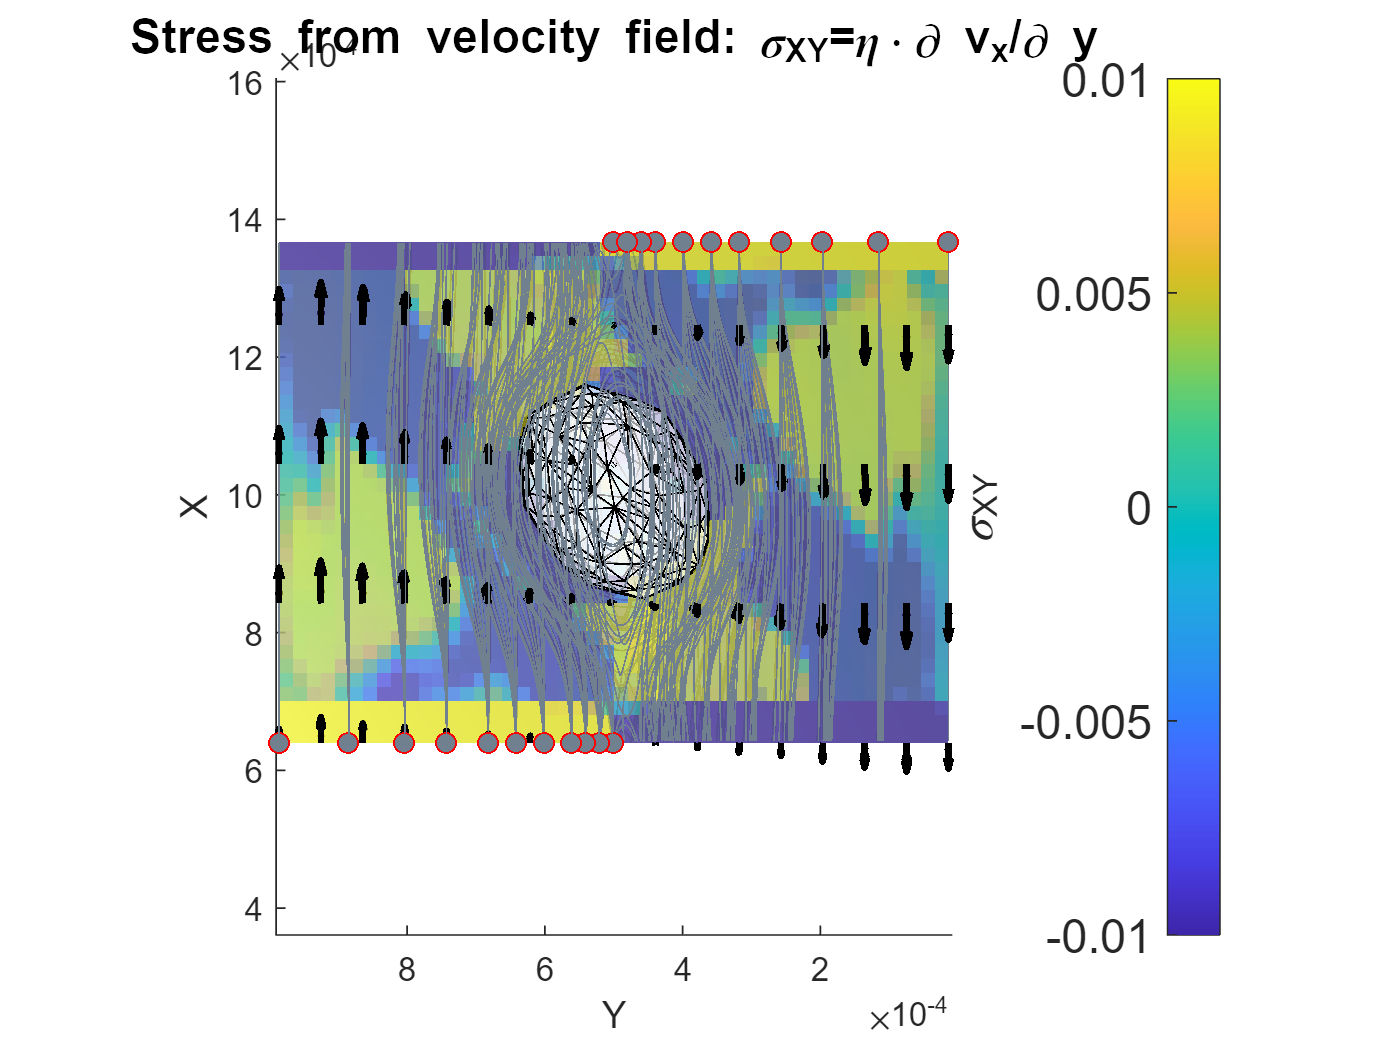

% === Plot Estimated shear stress (it should be the theoretical value)
figure, hold on
hs = slice(Xw,Yw,Zw,s12grid_est,[boxcenter(1) xw(end)],...
    [boxcenter(2) yw(end)],...
    [fluidbox(3,1) boxcenter(3)]);
set(hs,'edgecolor','none','facealpha',0.6)
plotsolid()
lighting gouraud, camlight('left'), axis equal, view(3) % shading interp
hc = colorbar('AxisLocation','in','fontsize',14); hc.Label.String = '\sigma_{XY}';
title('Stress from velocity field: \sigma_{XY}=\eta\cdot\partial v_x/\partial y','fontsize',14)
xlabel('X'), ylabel('Y'), zlabel('Z')
step = [3 10 5];
quiver3( ...
    Xw(1:step(1):end,1:step(2):end,1:step(3):end), ...
    Yw(1:step(1):end,1:step(2):end,1:step(3):end), ...
    Zw(1:step(1):end,1:step(2):end,1:step(3):end), ...
    vXYZgridx(1:step(1):end,1:step(2):end,1:step(3):end), ...
    vXYZgridy(1:step(1):end,1:step(2):end,1:step(3):end), ...
    vXYZgridz(1:step(1):end,1:step(2):end,1:step(3):end) ...
    ,1,'color','k','LineWidth',2)
npart = 30;
[startX,startY,startZ] = meshgrid( ...
    double(xw(1)), ...
    double(yw(unique(round(1+(1+(linspace(-1,1,npart).*linspace(-1,1,npart).^2))*floor(length(yw)/2))))),...
    double(yw(unique(round(1+(1+(linspace(-1,1,npart).*linspace(-1,1,npart).^2))*floor(length(yw)/2))))) ...
  );
vstart = interp3(Xw,Yw,Zw,vXYZgridx,startX,startY,startZ); startX(vstart<0) = double(xw(end));
hsl = streamline(double(Xw),double(Yw),double(Zw),vXYZgridx,vXYZgridy,vXYZgridz,startX,startY,startZ);
set(hsl,'linewidth',0.5,'color',[0.4375    0.5000    0.5625])
plot3(startX(:),startY(:),startZ(:),'ro','markerfacecolor',[0.4375    0.5000    0.5625])
% fix the view
view(-90,90), clim([-1e-2 1e-2])

The figure is plotting the shear-stress, the velocity field and stream lines. The top view is showing the local turbulence and heterogenieity in shear. The pattern at the entrance and outlet of the channel are numerical errors on the gradient.

### 4.3. Plot the shear stress from Cauchy tensor

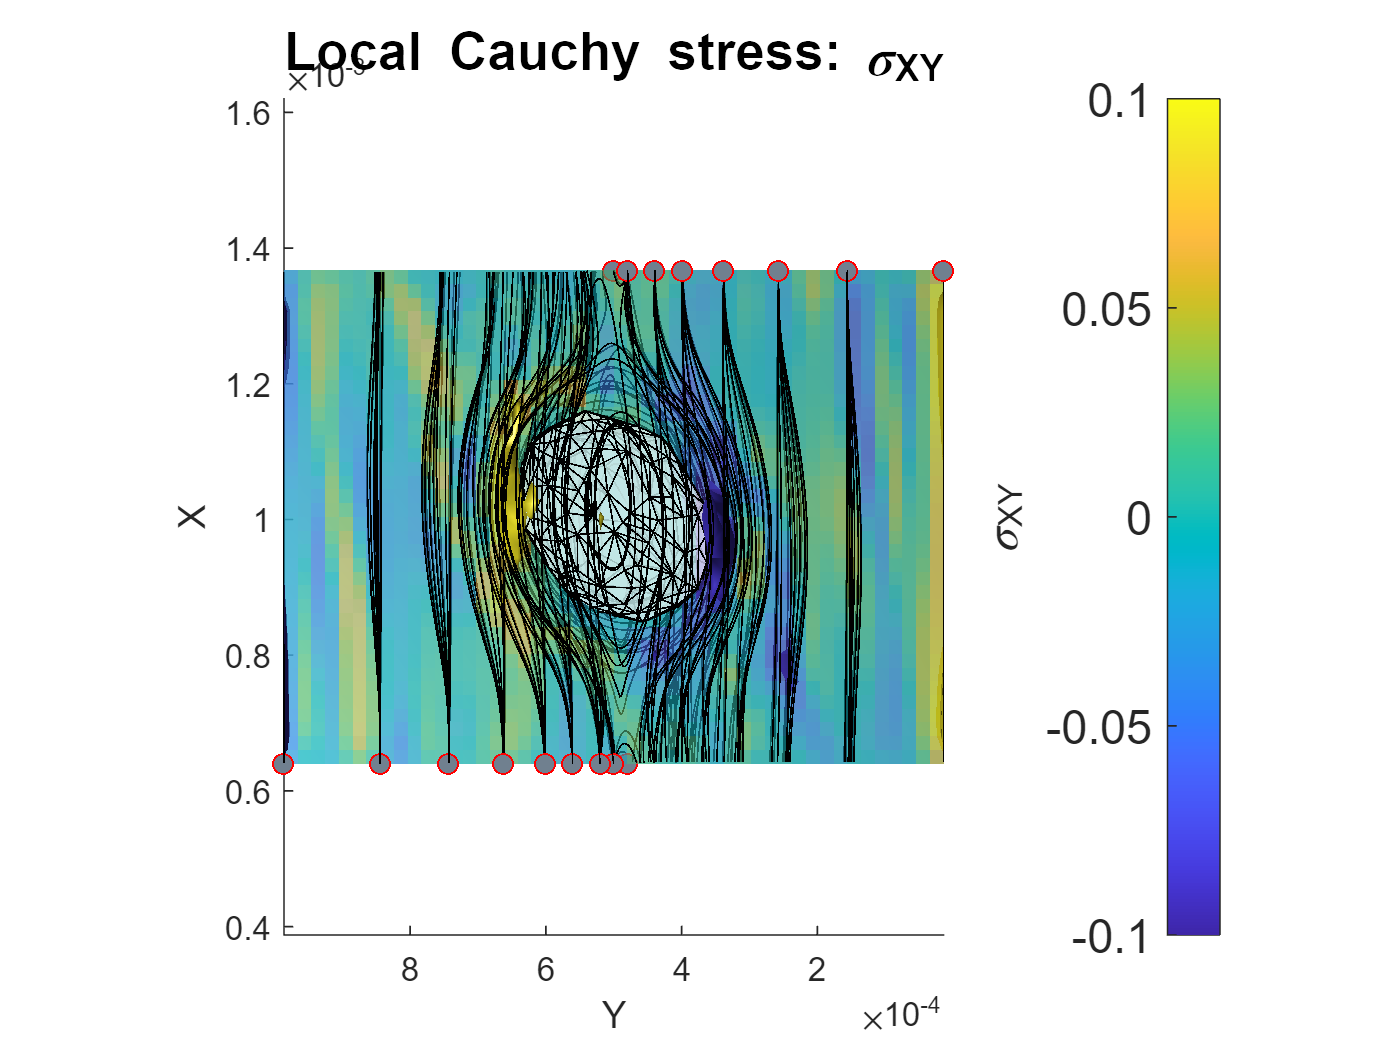

% === Plot Estimated shear stress from Cauchy Tensor
figure, hold on
s1299 = prctile(abs(s12grid2(~isnan(s12grid2))),99);
isosurface(Xw,Yw,Zw,s12grid2,s1299)
isosurface(Xw,Yw,Zw,s12grid2,-s1299)
hs = slice(Xw,Yw,Zw,s12grid2,[boxcenter(1) xw(end)],...
    [boxcenter(2) yw(end)],...
    [fluidbox(3,1) boxcenter(3)]);
set(hs,'edgecolor','none','facealpha',0.6)
plotsolid()
lighting gouraud, camlight('left'), axis equal, view(3) % shading interp
hc = colorbar('AxisLocation','in','fontsize',14); hc.Label.String = '\sigma_{XY}';
title('Local Cauchy stress: \sigma_{XY}','fontsize',16)
xlabel('X'), ylabel('Y'), zlabel('Z')
npart = 20;
[startX,startY,startZ] = meshgrid( ...
    double(xw(1)), ...
    double(yw(unique(round(1+(1+(linspace(-1,1,npart).*linspace(-1,1,npart).^2))*floor(length(yw)/2))))),...
    double(yw(unique(round(1+(1+(linspace(-1,1,npart).*linspace(-1,1,npart).^2))*floor(length(yw)/2))))) ...
  );
vstart = interp3(Xw,Yw,Zw,vXYZgridx,startX,startY,startZ); startX(vstart<0) = double(xw(end));
hsl = streamline(double(Xw),double(Yw),double(Zw),vXYZgridx,vXYZgridy,vXYZgridz,startX,startY,startZ);
set(hsl,'linewidth',0.5,'color','k')
plot3(startX(:),startY(:),startZ(:),'ro','markerfacecolor',[0.4375    0.5000    0.5625])
view(-90,90), clim([-1e-1 1e-1])

The top view shows a symmetric structure with two regions (isosurfaces corresponding to $1^{st}$ (blue) and $99^{th}$ (yellow)) with very high shear. They are reponsible of the deformation and the alignment of the particle. The solid particle presents an angle with the main axes of the channel. This angle reduces the cross-section of passage for the flow.

For a further discusssion on orientation effects, read: [Computers & Mathematics with Applications 2020, 79(3) 539-554](https://doi.org/10.1016/j.camwa.2018.12.039).

### 4.4. Plot the local virial stress

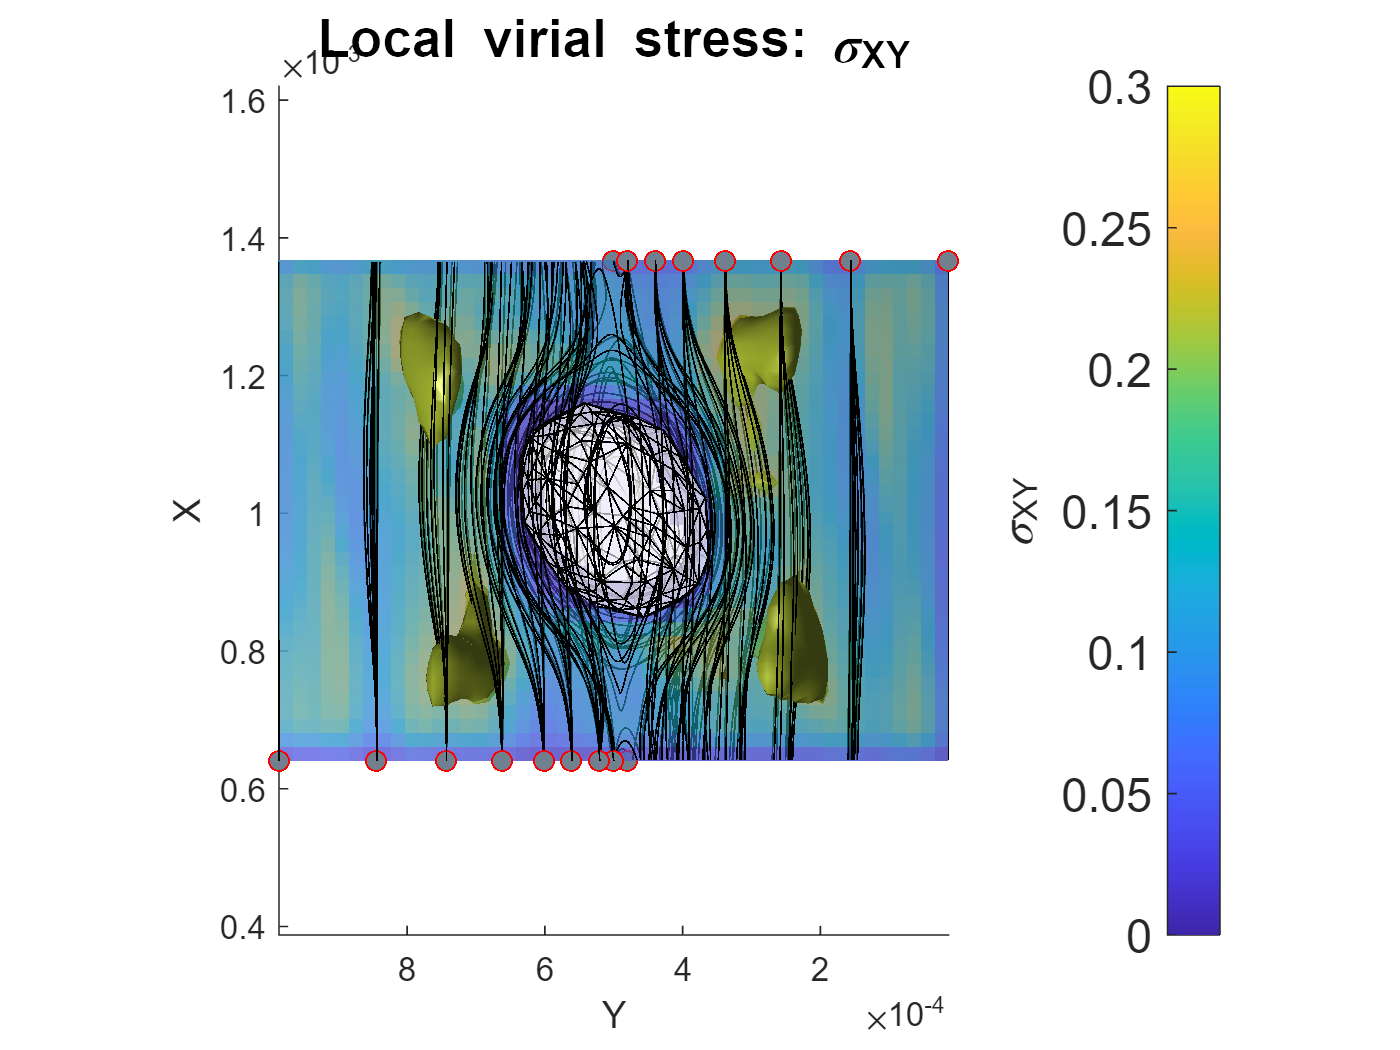

% === Plot local virial stess: s12 (s12 is stored as s(2,1))
figure, hold on
s1299 = prctile(abs(s12grid(~isnan(s12grid))),99);
isosurface(Xw,Yw,Zw,s12grid,s1299)
isosurface(Xw,Yw,Zw,s12grid,-s1299)
hs = slice(Xw,Yw,Zw,s12grid,[boxcenter(1) xw(end)],...
    [boxcenter(2) yw(end)],...
    [fluidbox(3,1) boxcenter(3)]);
set(hs,'edgecolor','none','facealpha',0.6)
plotsolid()
lighting gouraud, camlight('left'), axis equal, view(3) % shading interp
hc = colorbar('AxisLocation','in','fontsize',14); hc.Label.String = '\sigma_{XY}';
title('Local virial stress: \sigma_{XY}','fontsize',16)
xlabel('X'), ylabel('Y'), zlabel('Z')
npart = 20;
[startX,startY,startZ] = meshgrid( ...
    double(xw(1)), ...
    double(yw(unique(round(1+(1+(linspace(-1,1,npart).*linspace(-1,1,npart).^2))*floor(length(yw)/2))))),...
    double(yw(unique(round(1+(1+(linspace(-1,1,npart).*linspace(-1,1,npart).^2))*floor(length(yw)/2))))) ...
  );
vstart = interp3(Xw,Yw,Zw,vXYZgridx,startX,startY,startZ); startX(vstart<0) = double(xw(end));
hsl = streamline(double(Xw),double(Yw),double(Zw),vXYZgridx,vXYZgridy,vXYZgridz,startX,startY,startZ);
set(hsl,'linewidth',0.5,'color','k')
plot3(startX(:),startY(:),startZ(:),'ro','markerfacecolor',[0.4375    0.5000    0.5625])
view(-90,90), clim([0 0.3])

The scales of virial estimates despite being poorly resolved are consistent with Cauchy stress reconstruction.

### 4.5. Plot the Landschoff forces (not stress) - for control

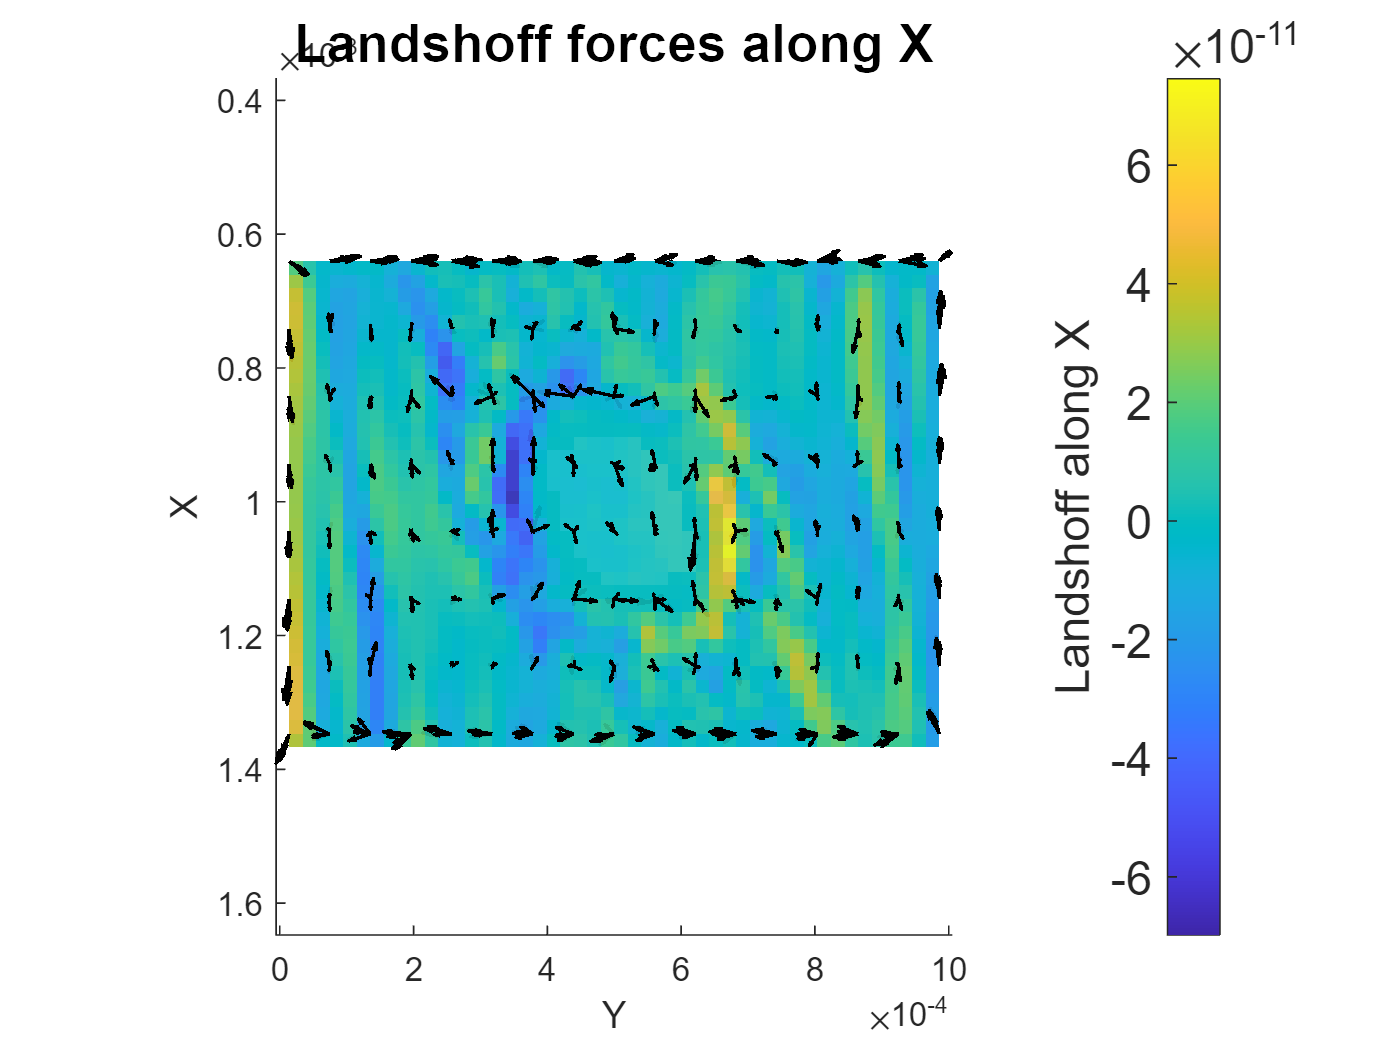

% === PLot Landshoff forces only 
figure, hold on
hs = slice(Xw,Yw,Zw,FXYZgridx,[xw(1) boxcenter(1)],...
    [yw(2) boxcenter(2) yw(end)],...
    [fluidbox(3,1) boxcenter(3)]);
set(hs,'edgecolor','none','facealpha',0.9)
axis equal, view(3),
hc = colorbar('AxisLocation','in','fontsize',14); hc.Label.String = 'Landshoff along X';
xlabel('X'), ylabel('Y'), zlabel('Z')
title('Landshoff forces along X','fontsize',16)
step = [3 5 5];
quiver3( ...
    Xw(1:step(1):end,1:step(2):end,1:step(3):end), ...
    Yw(1:step(1):end,1:step(2):end,1:step(3):end), ...
    Zw(1:step(1):end,1:step(2):end,1:step(3):end), ...
    FXYZgridx(1:step(1):end,1:step(2):end,1:step(3):end), ...
    FXYZgridy(1:step(1):end,1:step(2):end,1:step(3):end), ...
    FXYZgridz(1:step(1):end,1:step(2):end,1:step(3):end) ...
    ,1,'color','k','LineWidth',1)
view(90,90)

The top view illustrate the symmetry of the forces. The color shows the extent of the $x$-component and the arrows the direction and magnitude of the forces.,The previously presented stress estimates are consistent with forces.

## 5. Hertz contact stresses interpreted as fluid-solid shear stress

This section repeats analyzes introduced in `example2` on triangular meshes.

### 5.1 Computation part

The values `Rfluid` and `Rsolid` deserve clarificaiton for more accurate Hertz contact determination.

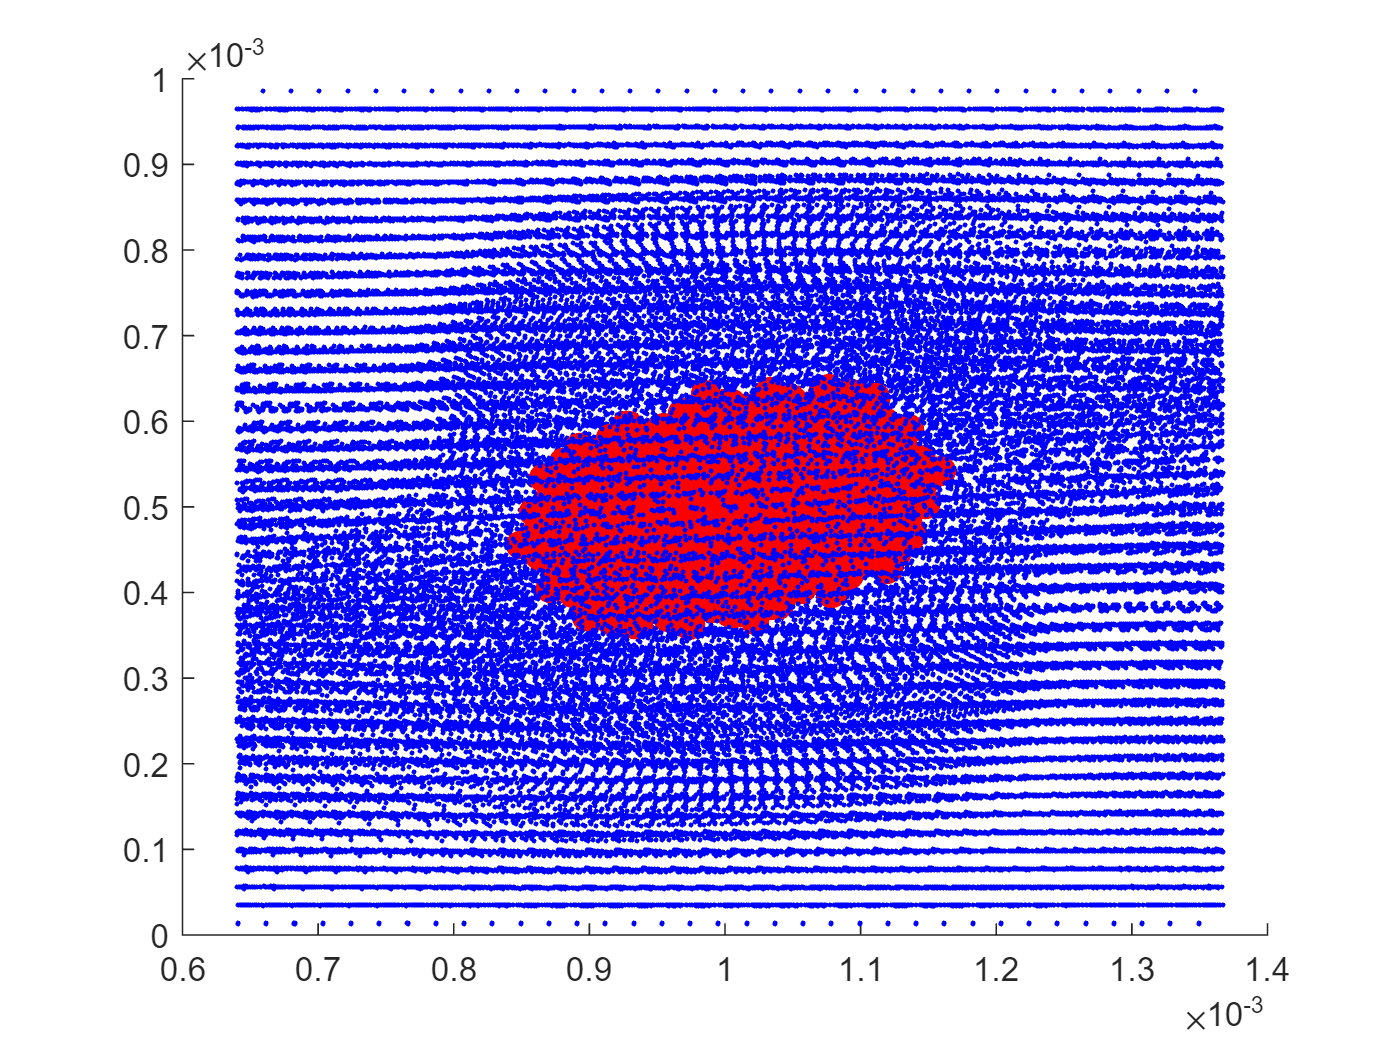

%% Hertz contact solid-fluid
% ===========================
XFluidSolid = Xstress.ATOMS(union(ifluid,isolid),:);
figure, hold on
plot3D(XFluidSolid{XFluidSolid.isfluid,coords},'bo','markersize',1,'markerfacecolor','b')
plot3D(XFluidSolid{XFluidSolid.issolid,coords},'ro','markersize',8,'markerfacecolor','r')

Rfluid = 1.04e-5; % m
Rsolid = 1.56e-5; % m
Rfluid = Rsolid;
hhertz = 2*Rsolid;
[Vcontactsolid,~,dmincontact] = buildVerletList(XFluidSolid,hhertz,[],[],[],XFluidSolid.isfluid,XFluidSolid.issolid);

Build Verlet list by searching in blocks...
... done in 0.155 s with 80 search blocks | minimum distance Inf
	 Sort the Verlet list...
	 ... done in 0.137 s
buildVerletList: all done in 0.34 s for 78705 atoms


configHertz = struct('R',{Rsolid Rfluid},'E',2000,'rho',1000,'m',9.04e-12,'h',hhertz);
[FHertzSolid,WHertzSolid] = forceHertz(XFluidSolid,Vcontactsolid,configHertz);
fhertz = sqrt(sum(FHertzSolid.^2,2));
statvec(fhertz(fhertz>0),'Hertz',sprintf('<-- TIMESTEP: %d\n\tsubjected to Rsolid=[%0.4g %0.4g] dmin/2=%0.4g',timestepforstress,configHertz(1).R,configHertz(2).R,dmincontact/2))

Hertz:  2.5%>  9.734e-09 |  25.0%>  3.971e-08 |  50.0%>  6.793e-08 |  75.0%>  8.941e-08 |  97.5%>  1.058e-07 | 586 values | average = 6.3672e-08 <-- TIMESTEP: 1000000
	subjected to Rsolid=[1.56e-05 1.56e-05] dmin/2=Inf



% project Hertz contact on accurate grid (Cartesian)
soliddbox = [ min(Xstress.ATOMS{isolid,coords})-4*rbead
              max(Xstress.ATOMS{isolid,coords})+4*rbead ]';
boxcenter = mean(soliddbox,2);
resolution = ceil(50 * diff(soliddbox,[],2)'./max(diff(soliddbox,[],2)));
xw = linspace(soliddbox(1,1),soliddbox(1,2),resolution(1));
yw = linspace(soliddbox(2,1),soliddbox(2,2),resolution(2));
zw = linspace(soliddbox(3,1),soliddbox(3,2),resolution(3));
[Xw,Yw,Zw] = meshgrid(xw,yw,zw);
XYZgrid = [Xw(:),Yw(:),Zw(:)];
VXYZ = buildVerletList({XYZgrid XFluidSolid{:,coords}},1.1*hhertz);

Build Verlet list by searching in blocks...
... done in 0.202 s with 80 search blocks | minimum distance 2.673e-07
	 Sort the Verlet list...
	 ... done in 0.49 s
buildVerletList: all done in 12.8 s for 189105 grid points


W = kernelSPH(hhertz,'lucy',3); % kernel for interpolation (not gradkernel!)
FXYZgrid = interp3SPHVerlet(XFluidSolid{:,coords},FHertzSolid,XYZgrid,VXYZ,W,Vbead);

INTERP3SPHVERLET interpolates 110400 x 3 grid points with a Verlet list including from 12 to 26 neighbors...
...done in 7.104 s. INTERP3SPHVerlet completed the interpolation of 110400 points with 78705 kernels


FXYZgridx = reshape(FXYZgrid(:,1),size(Xw));
FXYZgridy = reshape(FXYZgrid(:,2),size(Yw));
FXYZgridz = reshape(FXYZgrid(:,3),size(Zw));
WXYZgrid2 = interp3cauchy(Xw,Yw,Zw,FXYZgridx,FXYZgridy,FXYZgridz);

Calculate the local Cauchy stress from a [46 x 50 x 48] grid...
	 ... done in 8.81 s from 110400 GRIDPOINTS


s12grid2 = reshape(WXYZgrid2(:,:,:,2),size(Xw));

### 5.2 Rapid plot of Hertz forces around the solid particle

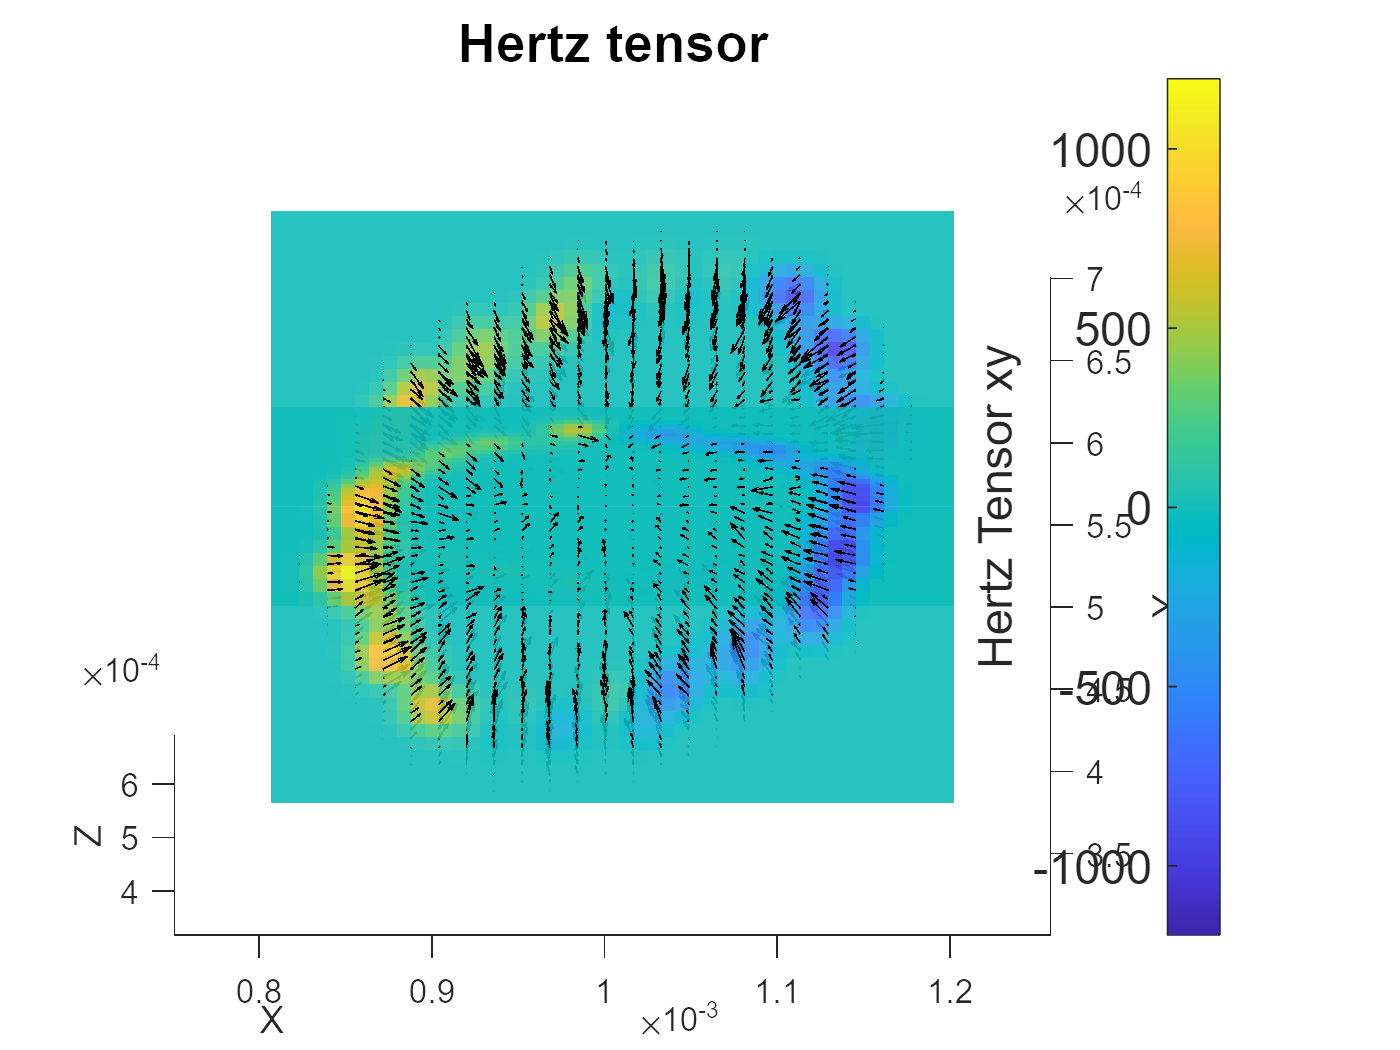

%% Rough plot of Hertz Contact Tensor (component xy) - SOLID-FLUID
figure, hold on
hs = slice(Xw,Yw,Zw,s12grid2, ...
    boxcenter(1),...
    boxcenter(2),...
    boxcenter(3));
set(hs,'edgecolor','none','facealpha',0.9)
axis equal, view(3),
hc = colorbar('AxisLocation','in','fontsize',14); hc.Label.String = 'Hertz Tensor xy';
xlabel('X'), ylabel('Y'), zlabel('Z')
title('Hertz tensor','fontsize',16)
step = [2 2 2];
quiver3( ...
    Xw(1:step(1):end,1:step(2):end,1:step(3):end), ...
    Yw(1:step(1):end,1:step(2):end,1:step(3):end), ...
    Zw(1:step(1):end,1:step(2):end,1:step(3):end), ...
    FXYZgridx(1:step(1):end,1:step(2):end,1:step(3):end), ...
    FXYZgridy(1:step(1):end,1:step(2):end,1:step(3):end), ...
    FXYZgridz(1:step(1):end,1:step(2):end,1:step(3):end) ...
    ,1.5,'color','k','LineWidth',0.5)
view(0,72)

The tensor component $xy$ is shown as colors. The arrows represent the Hertz forces.

### 5.3. Advanced shear-stress projected onto the solid particle

%% Advanced plot for Hertz Contacts
% almost same code as example2: 

% === STEP 1/5 === Original Delaunay triangulation and the convex hull
% this step has been already done as the begining of example2bis.m
% DT = delaunayTriangulation(double(Xstress.ATOMS{isolidcontact, coords}));
% K = convexHull(DT);
% === STEP 2/5 === refine the initial mesh by adding midpoints
% Extract the convex hull points and faces
hullPoints = DT.Points;
hullFaces = DT.ConnectivityList(K, :);
% Initialize a set to keep track of midpoints to ensure they are unique
midpointSet = zeros(0, 3);
% Calculate midpoints for each edge in each triangle and add to the point list
for faceIdx = 1:size(hullFaces, 1)
    face = hullFaces(faceIdx, :);
    for i = 1:3
        for j = i+1:3
            midpoint = (hullPoints(face(i), :) + hullPoints(face(j), :)) / 2;        
            if isempty(midpointSet) || ~ismember(midpoint, midpointSet, 'rows')
                midpointSet = [midpointSet; midpoint]; %#ok<AGROW>
            end
        end
    end
end
% Merge the original points and the new midpoints, update the the Delaunay triangulation
newDT = delaunayTriangulation([hullPoints; midpointSet]);
newK = convexHull(newDT);
% === STEP 3/5 ===  Laplacian Smoothing
points = newDT.Points;         % === Extract points and faces
faces = newDT.ConnectivityList(newK, :);
n = size(points, 1);           % === Initialize new points
newPoints = zeros(size(points)); 
neighbors = cell(n, 1);        % List of neighbors
for faceIdx = 1:size(faces, 1) % === Find the neighbors of each vertex
    face = faces(faceIdx, :);
    for i = 1:3
        vertex = face(i);
        vertex_neighbors = face(face ~= vertex);
        neighbors{vertex} = unique([neighbors{vertex}; vertex_neighbors(:)]);
    end
end
for i = 1:n                   % === Laplacian smoothing
    neighbor_indices = neighbors{i};
    if isempty(neighbor_indices) % Keep the point as is if it has no neighbors
        newPoints(i, :) = points(i, :); 
    else % Move the point to the centroid of its neighbors
        newPoints(i, :) = mean(points(neighbor_indices, :), 1);
    end
end
% Update the Delaunay triangulation with the smoothed points
newDT = delaunayTriangulation(newPoints);
newK = convexHull(newDT);
% === STEP 4/5 === Interpolate the Hertz forces on the triangular mesh
XYZhtri = newDT.Points;
XYZh = XFluidSolid{:,coords}; % kernel centers
VXYZh = buildVerletList({XYZhtri XFluidSolid{:,coords}},1.1*hhertz); % special grid syntax

Build Verlet list by searching in blocks...
... done in 0.1746 s with 80 search blocks | minimum distance 0
	 Sort the Verlet list...
	 ... done in 0.122 s
buildVerletList: all done in 0.346 s for 80026 grid points


W = kernelSPH(hhertz,'lucy',3); % kernel expression
FXYZtri = interp3SPHVerlet(XFluidSolid{:,coords},FHertzSolid,XYZhtri,VXYZh,W,Vbead);

INTERP3SPHVERLET interpolates 1081 x 3 grid points with a Verlet list including from 13 to 23 neighbors...
...done in 0.05759 s. INTERP3SPHVerlet completed the interpolation of 1081 points with 78945 kernels


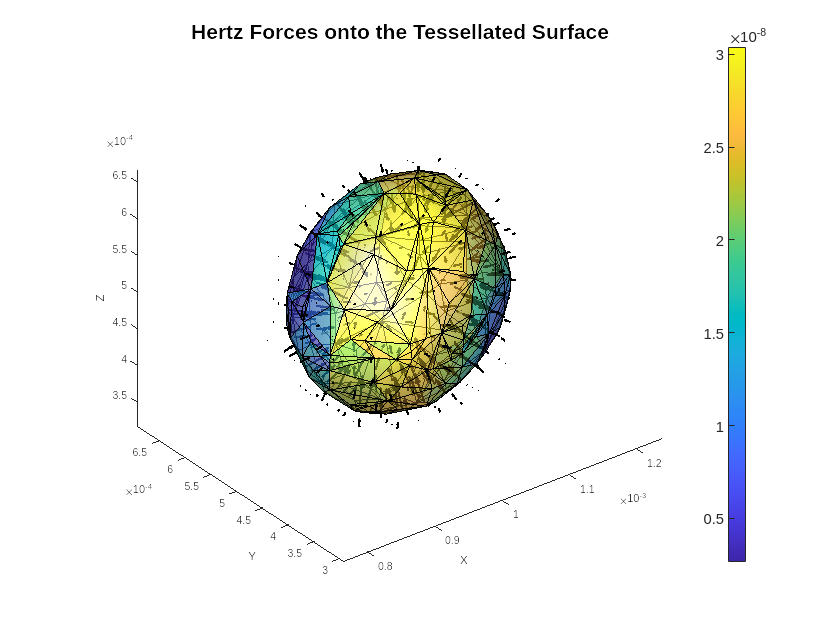

% === STEP 5/5 === Extract tagential forces
% Calculate face normals and centroids
points = newDT.Points;
faces = newK;
v1 = points(faces(:, 1), :) - points(faces(:, 2), :);
v2 = points(faces(:, 1), :) - points(faces(:, 3), :);
faceNormals = cross(v1, v2, 2);
faceNormals = faceNormals ./ sqrt(sum(faceNormals.^2, 2));
centroids = mean(reshape(points(faces, :), size(faces, 1), 3, 3), 3);
% Interpolate force at each centroid using scatteredInterpolant for each component
FInterp_x = scatteredInterpolant(XYZhtri, double(FXYZtri(:,1)), 'linear', 'nearest');
FInterp_y = scatteredInterpolant(XYZhtri, double(FXYZtri(:,2)), 'linear', 'nearest');
FInterp_z = scatteredInterpolant(XYZhtri, double(FXYZtri(:,3)), 'linear', 'nearest');
FXYZtri_at_centroids = [FInterp_x(centroids), FInterp_y(centroids), FInterp_z(centroids)];
% Calculate normal and tangential components of the force at each face centroid
normalComponent = dot(FXYZtri_at_centroids, faceNormals, 2);
normalForce = repmat(normalComponent, 1, 3) .* faceNormals;
tangentialForce = FXYZtri_at_centroids - normalForce;
tangentialMagnitude = sqrt(sum(tangentialForce.^2, 2));
% Do the figure
figure, hold on
trisurfHandle = trisurf(newK, newDT.Points(:, 1), newDT.Points(:, 2), newDT.Points(:, 3), 'Edgecolor', 'k', 'FaceAlpha', 0.6);
set(trisurfHandle, 'FaceVertexCData', tangentialMagnitude, 'FaceColor', 'flat');
colorbar;
% Quiver plot to show the forces with an adjusted step
step = [2 2 2]*2;
quiver3( ...
    Xw(1:step(1):end,1:step(2):end,1:step(3):end), ...
    Yw(1:step(1):end,1:step(2):end,1:step(3):end), ...
    Zw(1:step(1):end,1:step(2):end,1:step(3):end), ...
    FXYZgridx(1:step(1):end,1:step(2):end,1:step(3):end), ...
    FXYZgridy(1:step(1):end,1:step(2):end,1:step(3):end), ...
    FXYZgridz(1:step(1):end,1:step(2):end,1:step(3):end) ...
    ,1.5,'color','k','LineWidth',2)
axis equal; view(3), camlight('headlight'); camlight('left'); lighting phong; colorbar;
title('Hertz Forces onto the Tessellated Surface','fontsize',20);
xlabel('X'); ylabel('Y'); zlabel('Z')
hc = colorbar('AxisLocation','in','fontsize',14); 

The colors represent the component tangential to the surface. The arrows represent the forces at the refined mesh as estimated from the grid interpolation.

## 6. Hertz contact stress interpreted as shear-stress at walls

### 6.1. Computation part

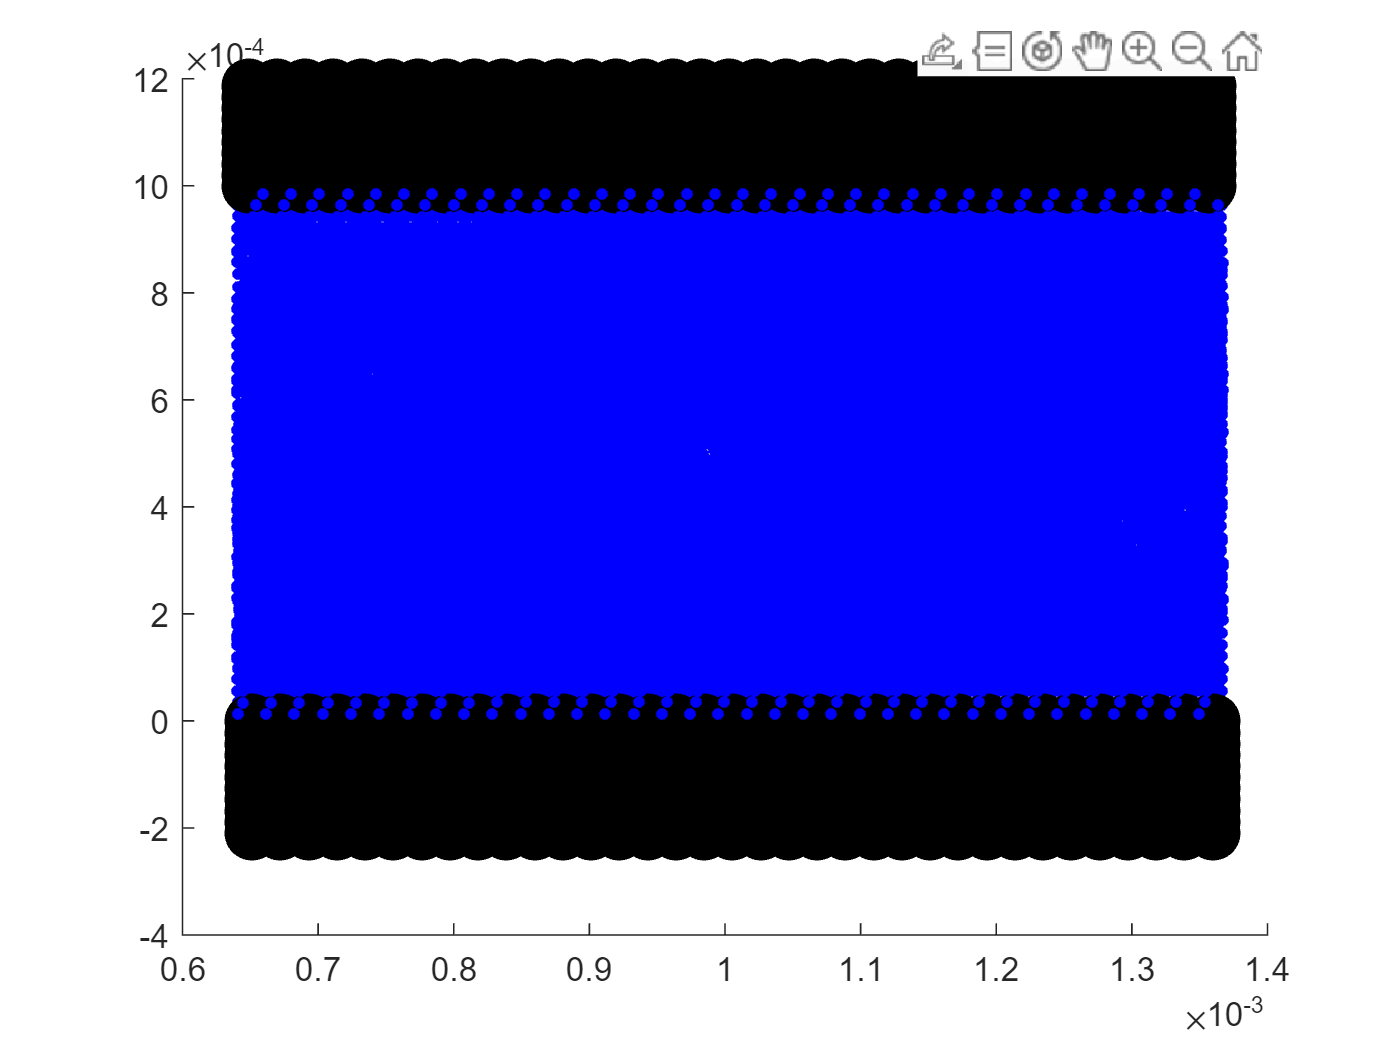

%% Hertz contact wall-fluid
% ==========================
XFluidWall = Xstress.ATOMS(union(ifluid,iwall),:);
figure, hold on
plot3D(XFluidWall{XFluidWall.isfluid,coords},'bo','markersize',1,'markerfacecolor','b')
plot3D(XFluidWall{XFluidWall.iswall,coords},'ko','markersize',8,'markerfacecolor','k')

Rfluid = 1.04e-5; % m
Rsolid = 1.56e-5; % m
Rfluid = Rsolid;
hhertz = 2*Rsolid;
[Vcontactwall,~,dmincontact] = buildVerletList(XFluidWall,hhertz,[],[],[],XFluidWall.isfluid,XFluidWall.iswall);

Build Verlet list by searching in blocks...
... done in 0.192 s with 180 search blocks | minimum distance Inf
	 Sort the Verlet list...
	 ... done in 0.205 s
buildVerletList: all done in 0.915 s for 112434 atoms


configHertz = struct('R',{Rsolid Rfluid},'E',2000,'rho',1000,'m',9.04e-12,'h',hhertz);
[FHertzWall,WHertzWall] = forceHertz(XFluidWall,Vcontactwall,configHertz);
fhertz = sqrt(sum(FHertzWall.^2,2));
statvec(fhertz(fhertz>0),'Hertz',sprintf('<-- TIMESTEP: %d\n\tsubjected to Rsolid=[%0.4g %0.4g] dmin/2=%0.4g',timestepforstress,configHertz(1).R,configHertz(2).R,dmincontact/2))

Hertz:  2.5%>  2.443e-07 |  25.0%>  3.922e-07 |  50.0%>  3.923e-07 |  75.0%>  3.924e-07 |  97.5%>  3.928e-07 | 3360 values | average = 3.8297e-07 <-- TIMESTEP: 1000000
	subjected to Rsolid=[1.56e-05 1.56e-05] dmin/2=Inf


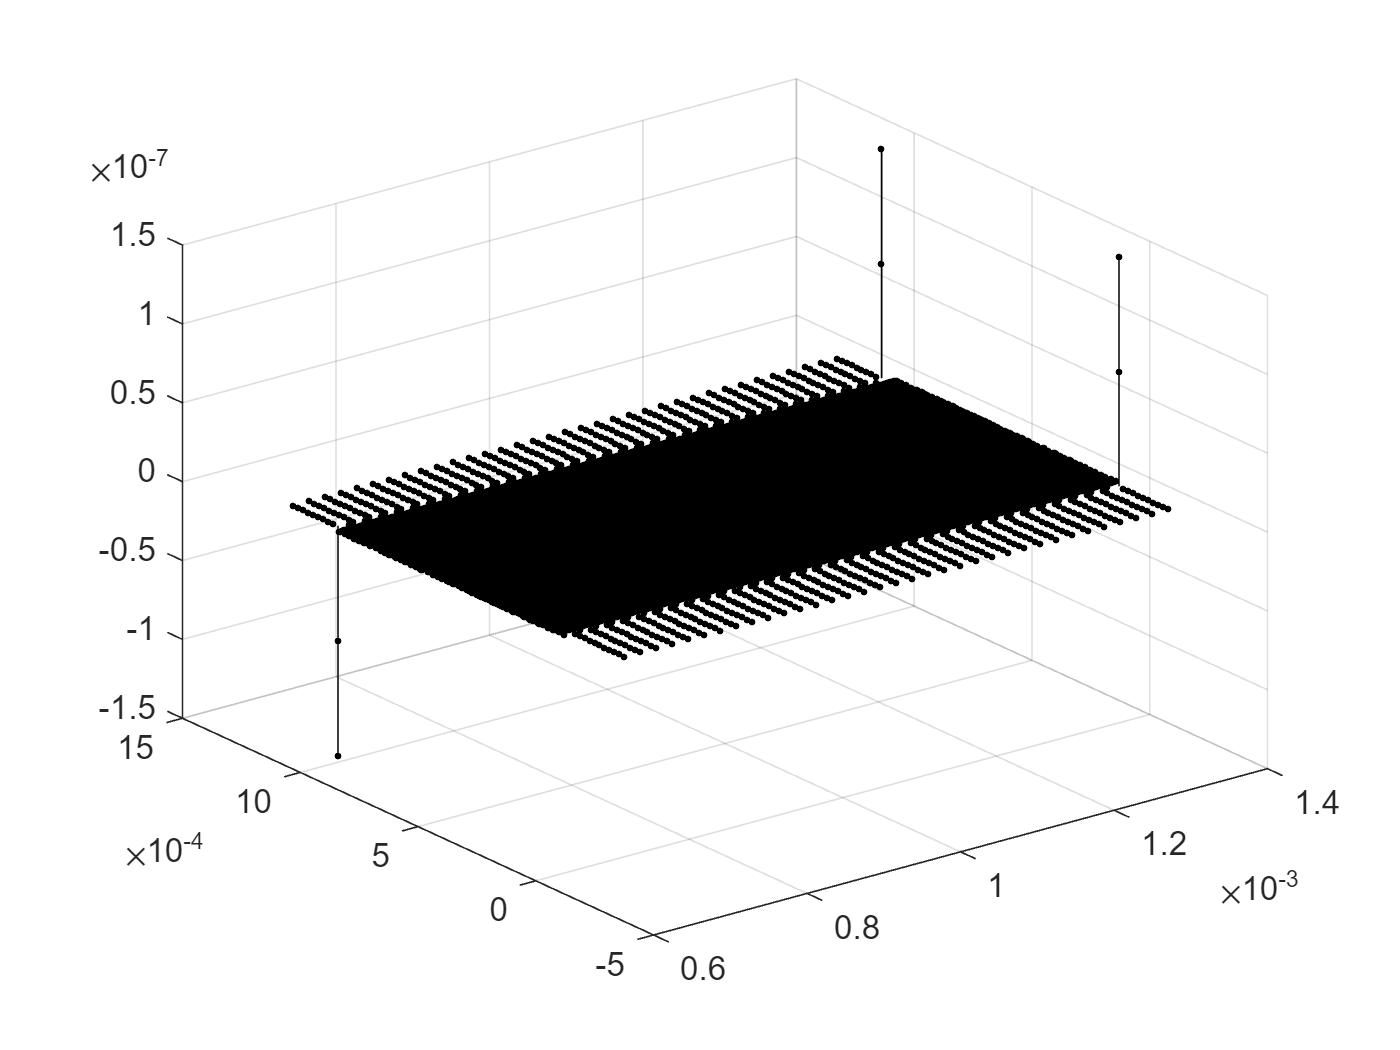

figure, stem3(XFluidWall.x,XFluidWall.y,FHertzWall(:,1),'k.')


% project Hertz contact on accurate grid (Cartesian)
[wallbox1,wallbox2] = deal(fluidbox);
wallbox1(2,1) = fluidbox(2,1) - 1.5*hhertz;
wallbox1(2,2) = fluidbox(2,1) + 1.5*hhertz;
wallbox2(2,1) = fluidbox(2,2) - 1.5*hhertz;
wallbox2(2,2) = fluidbox(2,2) + 1.5*hhertz;
boxcenter = mean(fluidbox,2);
boxcenter1 = mean(wallbox1,2);
boxcenter2 = mean(wallbox2,2);
resolution1 = ceil(120 * diff(wallbox1,[],2)'./max(diff(wallbox1,[],2)));
resolution2 = ceil(120 * diff(wallbox2,[],2)'./max(diff(wallbox2,[],2)));
xw = linspace(wallbox1(1,1),wallbox1(1,2),resolution1(1));
yw1 = linspace(wallbox1(2,1),wallbox1(2,2),resolution1(2));
yw2 = linspace(wallbox2(2,1),wallbox2(2,2),resolution2(2));
zw = linspace(wallbox1(3,1),wallbox1(3,2),resolution1(3));
[Xw,Yw,Zw] = meshgrid(xw,[yw1 boxcenter(2) yw2],zw);
XYZgrid = [Xw(:),Yw(:),Zw(:)];
VXYZ = buildVerletList({XYZgrid XFluidWall{:,coords}},1.1*hhertz);

Build Verlet list by searching in blocks...
... done in 0.355 s with 180 search blocks | minimum distance 4.991e-08
	 Sort the Verlet list...
	 ... done in 1.02 s
buildVerletList: all done in 35.9 s for 376434 grid points


W = kernelSPH(hhertz,'lucy',3); % kernel for interpolation (not gradkernel!)
FXYZgrid = interp3SPHVerlet(XFluidWall{:,coords},FHertzWall,XYZgrid,VXYZ,W,Vbead);

INTERP3SPHVERLET interpolates 264000 x 3 grid points with a Verlet list including from 0 to 27 neighbors...
...done in 16.82 s. INTERP3SPHVerlet completed the interpolation of 264000 points with 112434 kernels


FXYZgridx = reshape(FXYZgrid(:,1),size(Xw));
FXYZgridy = reshape(FXYZgrid(:,2),size(Yw));
FXYZgridz = reshape(FXYZgrid(:,3),size(Zw));
WXYZgrid2 = interp3cauchy(Xw,Yw,Zw,FXYZgridx,FXYZgridy,FXYZgridz);

Calculate the local Cauchy stress from a [25 x 88 x 120] grid...
	 ... done in 21.1 s from 264000 GRIDPOINTS


s12grid2 = reshape(WXYZgrid2(:,:,:,2),size(Xw));

### 6.2 Rough plot of Hertz stress at walls

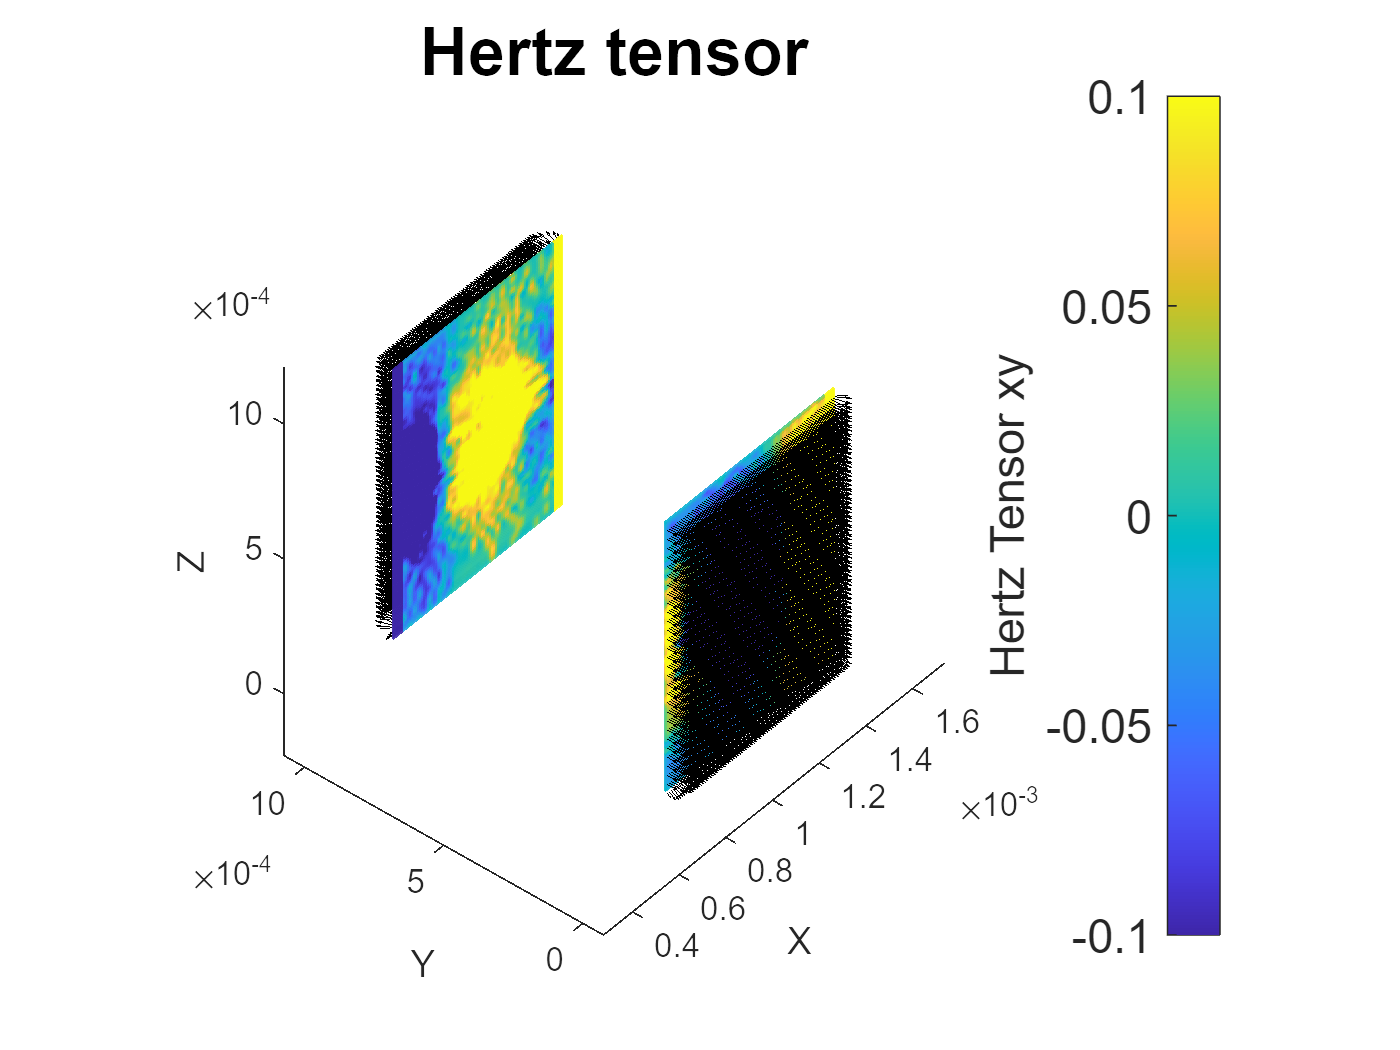

%% Rough plot of Hertz Contact Tensor (component xy)
figure, hold on
hs = slice(Xw,Yw,Zw,s12grid2, ...
    single([]),...
    [fluidbox(2,1)-[-.1 0 .1 0.5 1]*rbead/2 ,fluidbox(2,2)+[-.1 0 .1 0.5 1]*rbead/2],...
    single([]));
set(hs,'edgecolor','none','facealpha',0.9)
axis equal, view(3),
hc = colorbar('AxisLocation','in','fontsize',14); hc.Label.String = 'Hertz Tensor xy';
xlabel('X'), ylabel('Y'), zlabel('Z')
title('Hertz tensor','fontsize',20)
step = [4 1 4];
quiver3( ...
    Xw(1:step(1):end,1:step(2):end,1:step(3):end), ...
    Yw(1:step(1):end,1:step(2):end,1:step(3):end), ...
    Zw(1:step(1):end,1:step(2):end,1:step(3):end), ...
    FXYZgridx(1:step(1):end,1:step(2):end,1:step(3):end), ...
    FXYZgridy(1:step(1):end,1:step(2):end,1:step(3):end), ...
    FXYZgridz(1:step(1):end,1:step(2):end,1:step(3):end) ...
    ,.5,'color','k','LineWidth',.05)
caxis([-.1 .1]), view([-50,42])

The $xy$ Hertz resulting tensor stress is plotted as color for both wall surfaces with forces shown as quiver plots.